% 1.
% Общее решение 1-го уравнения: С1*e^(-4.1t) + C2*e^(4.1t).
% Общее решение 2-го уравнения: C1*e^(-4.1t) + t*C2*e^(-4.1t).
% В первом случае имеется положительный вещественный корень
% характеристического уравнения => y -> inf при t -> inf,
% что препятствует численному решению уравнения.
% Во втором случае корни характеристического уравнения отрицательные,
% поэтому не возникает проблем с использованием численных методов.

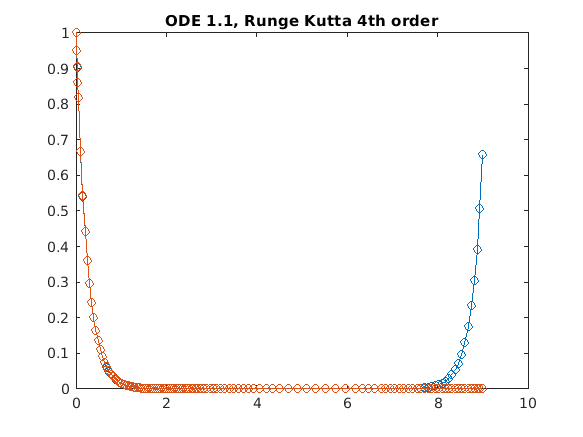

tspan = [0 9];
y0 = [1.0 -4.1];
[t,y] = ode45(@(t,y) [y(2); 16.81*y(1)], tspan, y0); 
plot(t,y(:,1),'-o',t,exp(t*-4.09),'-o')
title('ODE 1.1, Runge Kutta 4th order')

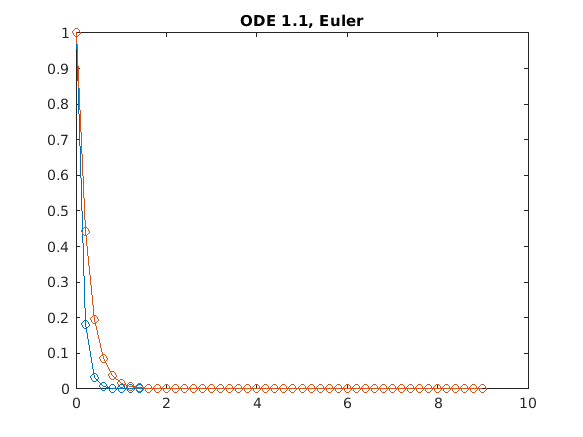

[t,y] = euler(@(t,y) [y(2), 16.81*y(1)], tspan, y0, 0.2); 
plot(t,y(:,1),'-o',t,exp(t*-4.09),'-o')
title('ODE 1.1, Euler')

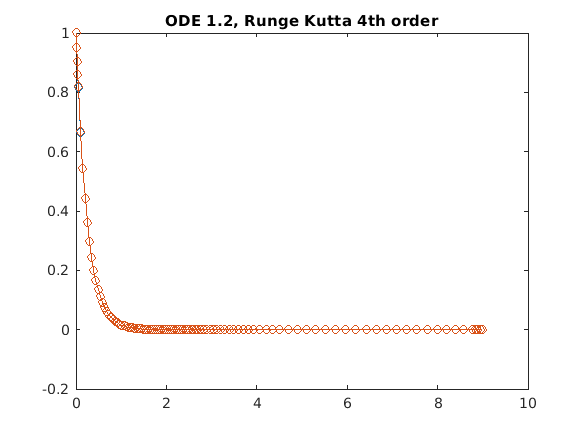

tspan = [0 9];
y0 = [1.0 -4.1];
[t,y] = ode45(@(t,y) [y(2); -8.2*y(2)-16.81*y(1)], tspan, y0); 
plot(t,y(:,1),'-o',t,exp(t*-4.09),'-o')
title('ODE 1.2, Runge Kutta 4th order')

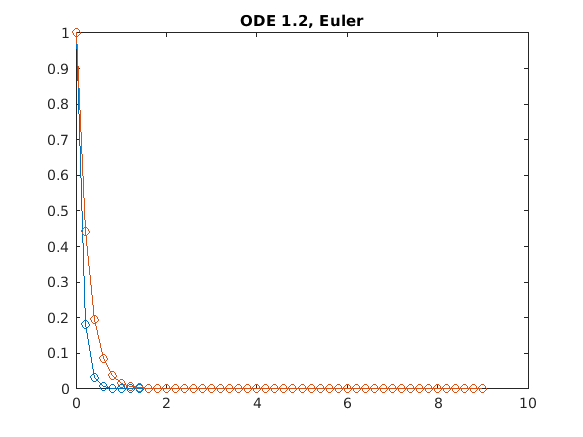

[t,y] = euler(@(t,y) [y(2), -8.2*y(2)-16.81*y(1)], tspan, y0, 0.2); 
plot(t,y(:,1),'-o',t,exp(t*-4.09),'-o')
title('ODE 1.2, Euler')

% 2.
% Для первой модели маятника
% при приближении sin(teta) = teta значения функций совпадают
% до значения teta'(0) = 2, когда маятник переворачивается через верхнюю
% точку, а решение нелинейной модели уходит на бесконечность, поведение же
% линейного аналога остается прежним.
%
% Нижнее положение равновесия (маятник вертикально вниз) устойчиво по Ляпунову 
% в отличие от верхнего (точка переворота маятника).
% Асимптотическую устойчивость по Ляпунову нулевого решения в линейной
% системе можно проверить, посчитав собственные числа A (их расположение в
% левой полуплоскости будет говорить об устойчивости по Ляпунову):
% x˙ = Ax , x ∈ E^n.
%
% Для второй модели с трением
% выводы аналогичны, но ее поведение меняется медленнее при изменении
% teta'(0).

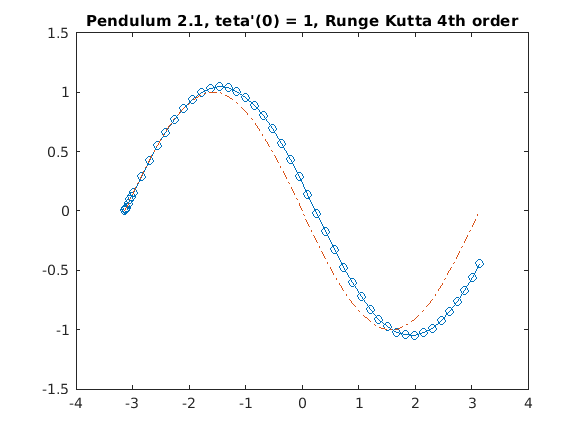

tspan = [-pi pi];
y0 = [0 1];
[~,y_full] = ode45(@(t,y) [y(2); -sin(y(1))], tspan, y0); 
[t,y_lin] = ode45(@(t,y) [y(2); -y(1)], tspan, y0); 
plot(t,y_full(:,1),'-o',t,y_lin(:,1),'-.')
title("Pendulum 2.1, teta'(0) = 1, Runge Kutta 4th order")

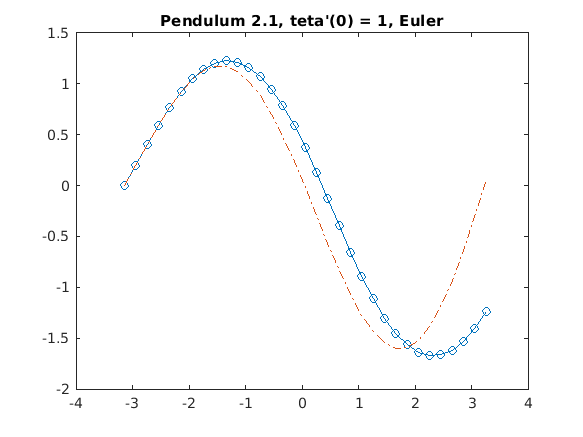

[~,y_full] = euler(@(t,y) [y(2), -sin(y(1))], tspan, y0, 0.2); 
[t,y_lin] = euler(@(t,y) [y(2), -y(1)], tspan, y0, 0.2); 
plot(t,y_full(:,1),'-o',t,y_lin(:,1),'-.')
title("Pendulum 2.1, teta'(0) = 1, Euler")

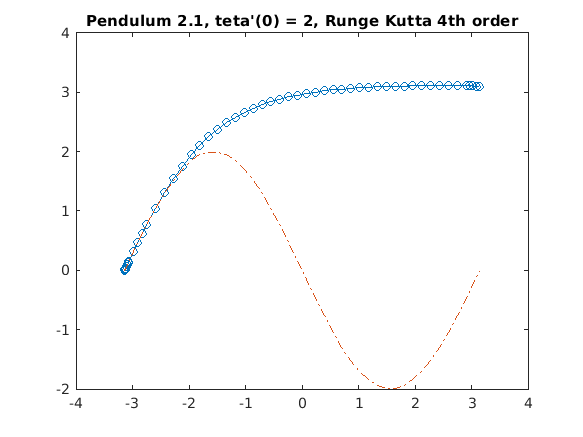

y0 = [0 2];
[~,y_full] = ode45(@(t,y) [y(2); -sin(y(1))], tspan, y0); 
[t,y_lin] = ode45(@(t,y) [y(2); -y(1)], tspan, y0); 
plot(t,y_full(:,1),'-o',t,y_lin(:,1),'-.')
title("Pendulum 2.1, teta'(0) = 2, Runge Kutta 4th order")

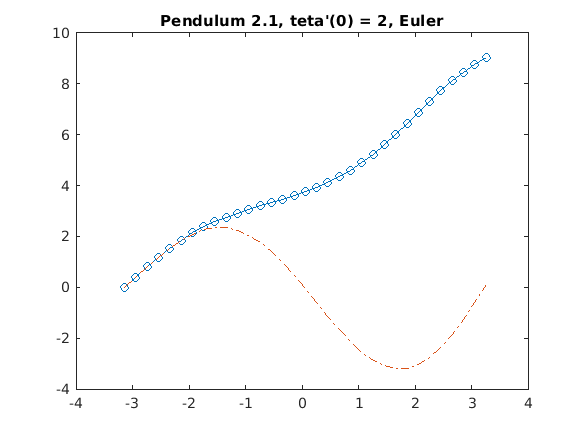

[~,y_full] = euler(@(t,y) [y(2), -sin(y(1))], tspan, y0, 0.2); 
[t,y_lin] = euler(@(t,y) [y(2), -y(1)], tspan, y0, 0.2); 
plot(t,y_full(:,1),'-o',t,y_lin(:,1),'-.')
title("Pendulum 2.1, teta'(0) = 2, Euler")

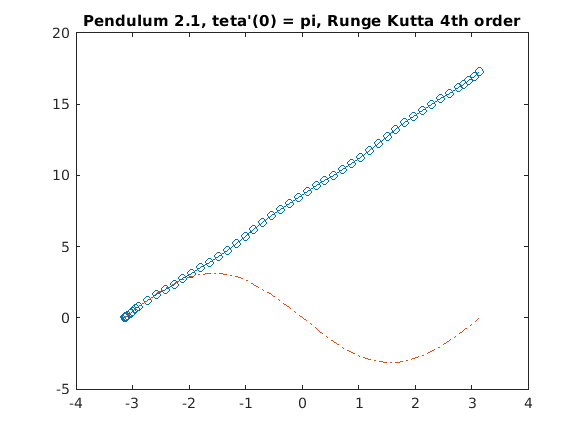

y0 = [0 pi];
[~,y_full] = ode45(@(t,y) [y(2); -sin(y(1))], tspan, y0); 
[t,y_lin] = ode45(@(t,y) [y(2); -y(1)], tspan, y0); 
plot(t,y_full(:,1),'-o',t,y_lin(:,1),'-.')
title("Pendulum 2.1, teta'(0) = pi, Runge Kutta 4th order")

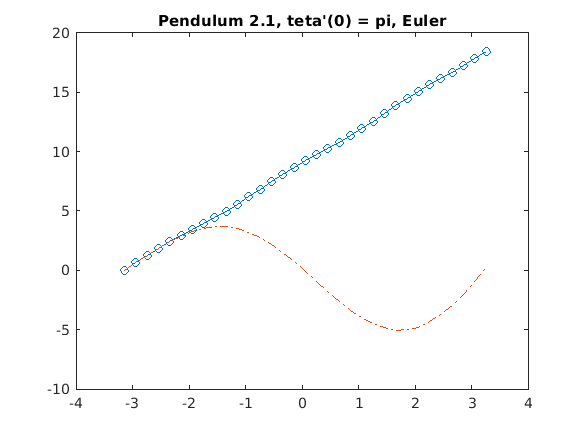

[~,y_full] = euler(@(t,y) [y(2), -sin(y(1))], tspan, y0, 0.2); 
[t,y_lin] = euler(@(t,y) [y(2), -y(1)], tspan, y0, 0.2); 
plot(t,y_full(:,1),'-o',t,y_lin(:,1),'-.')
title("Pendulum 2.1, teta'(0) = pi, Euler")

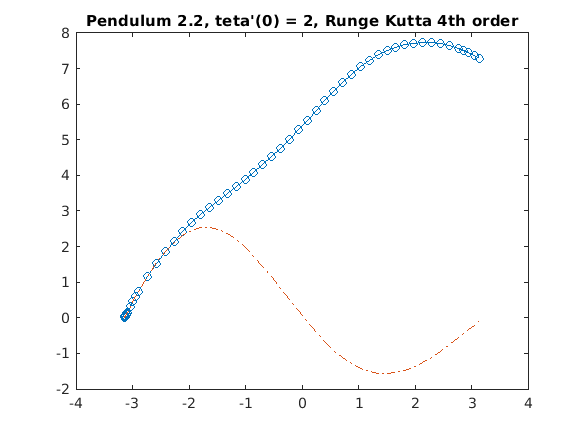

v = 0.3;
[~,y_full] = ode45(@(t,y) [y(2); -sin(y(1))-v*y(2)], tspan, y0); 
[t,y_lin] = ode45(@(t,y) [y(2); -y(1)-v*y(2)], tspan, y0);
plot(t,y_full(:,1),'-o',t,y_lin(:,1),'-.')
title("Pendulum 2.2, teta'(0) = 2, Runge Kutta 4th order")

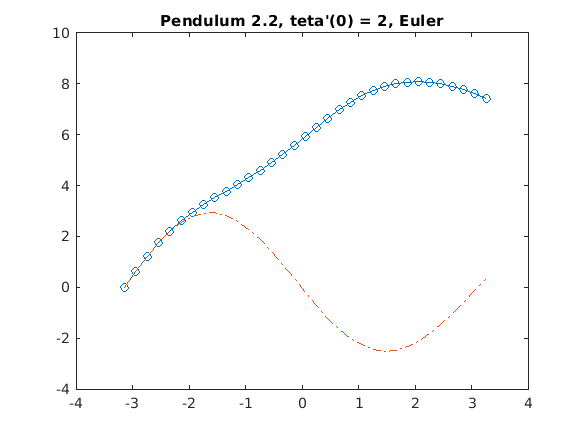

[~,y_full] = euler(@(t,y) [y(2), -sin(y(1))-v*y(2)], tspan, y0, 0.2); 
[t,y_lin] = euler(@(t,y) [y(2), -y(1)-v*y(2)], tspan, y0, 0.2); 
plot(t,y_full(:,1),'-o',t,y_lin(:,1),'-.')
title("Pendulum 2.2, teta'(0) = 2, Euler")

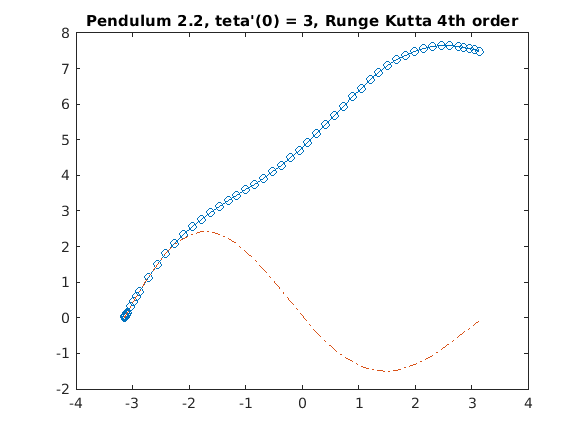

y0 = [0 3];
[~,y_full] = ode45(@(t,y) [y(2); -sin(y(1))-v*y(2)], tspan, y0);
[t,y_lin] = ode45(@(t,y) [y(2); -y(1)-v*y(2)], tspan, y0); 
plot(t,y_full(:,1),'-o',t,y_lin(:,1),'-.')
title("Pendulum 2.2, teta'(0) = 3, Runge Kutta 4th order")

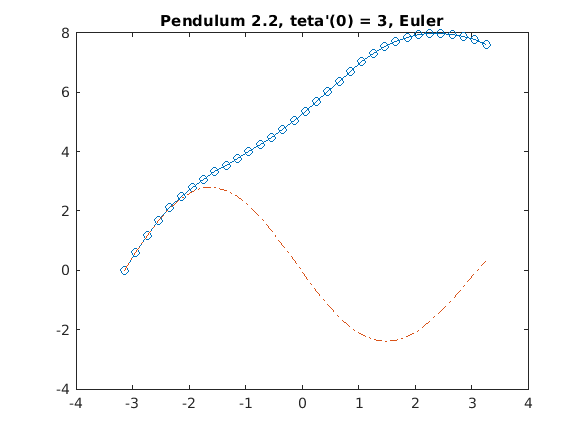

[~,y_full] = euler(@(t,y) [y(2), -sin(y(1))-v*y(2)], tspan, y0, 0.2); 
[t,y_lin] = euler(@(t,y) [y(2), -y(1)-v*y(2)], tspan, y0, 0.2); 
plot(t,y_full(:,1),'-o',t,y_lin(:,1),'-.')
title("Pendulum 2.2, teta'(0) = 3, Euler")

% 3.
% Рассмотрим разностную аппроксимацию производной для явного метода Эйлера:
% y(i+1) = y(i) + h*(-10000)*y(i) = R(a*h)*y(i).
% Метод будет устойчив при h < -2/(-10000) = 0.0002.
% Неявный метод Эйлера для данного примера рассчитывается по формуле:
% y(i+1) = y(i) / (1-a*h) = R(a*h)*y(i).
% R(a*h) < 1 при любом h => метод устойчив для любого h.

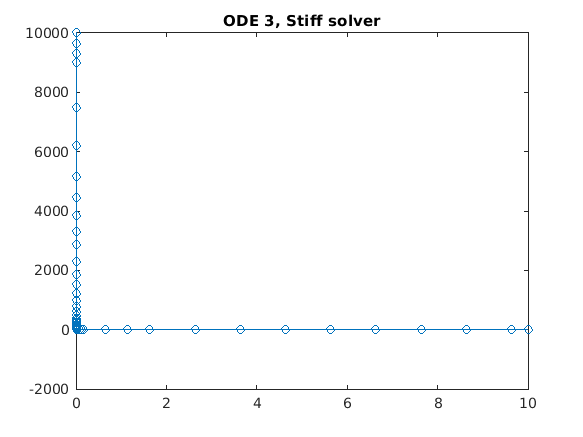

tspan = [0 10];
y0 = [10000 0];
[t,y_15s] = ode15s(@(t,y) -10000*y, tspan, y0); 
plot(t,y_15s(:,1),'-o')
title('ODE 3, Stiff solver')

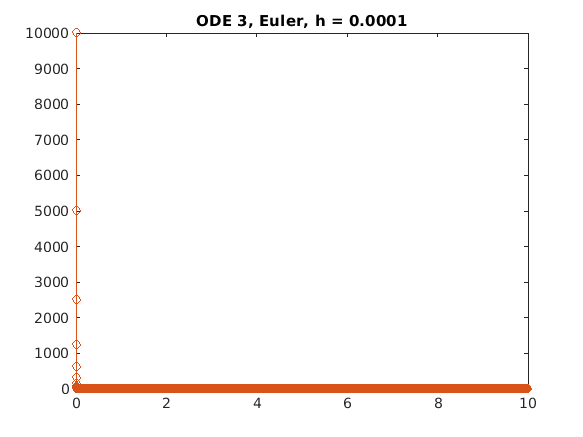

[~,y_exp] = euler(@(t,y) -10000*y, tspan, y0, 0.0001); 
[t,y_imp] = euler_imp(@(t,y) -10000*y, tspan, y0, 0.0001); 
plot(t,y_exp(:,1),'-o',t,y_imp(:,1),'-o')
title('ODE 3, Euler, h = 0.0001')

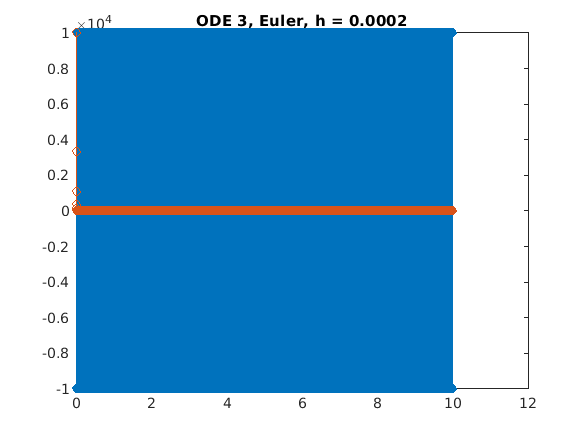

[~,y_exp] = euler(@(t,y) -10000*y, tspan, y0, 0.0002); 
[t,y_imp] = euler_imp(@(t,y) -10000*y, tspan, y0, 0.0002); 
plot(t,y_exp(:,1),'-o',t,y_imp(:,1),'-o')
title('ODE 3, Euler, h = 0.0002')

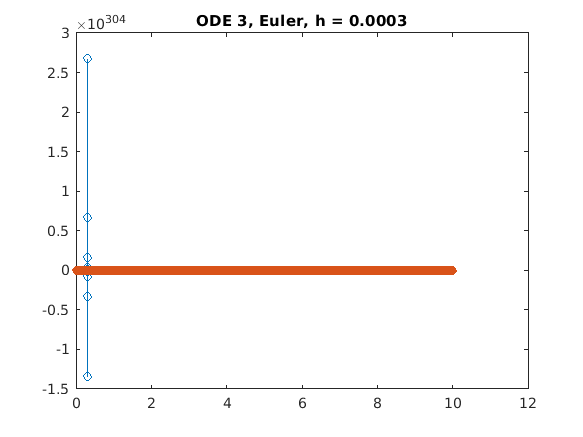

[~,y_exp] = euler(@(t,y) -10000*y, tspan, y0, 0.0003); 
[t,y_imp] = euler_imp(@(t,y) -10000*y, tspan, y0, 0.0003); 
plot(t,y_exp(:,1),'-o',t,y_imp(:,1),'-o')
title('ODE 3, Euler, h = 0.0003')

% 4.
% Число жесткости системы (max|lambda_i| / min|lambda_i| = 10^8) достаточно
% высоко, что объясняет невозможность ее решения методом Эйлера и большое
% число итераций, необходимых для метода Рунге -- Кутты 4-го порядка с
% автоматическим подбором шага.
% ode15s показывает себя отлично на данном примере, решая уравнение
% корректно за малое число итераций (их число возрастает лишь в окрестности
% точки, где резко изменяется производная).

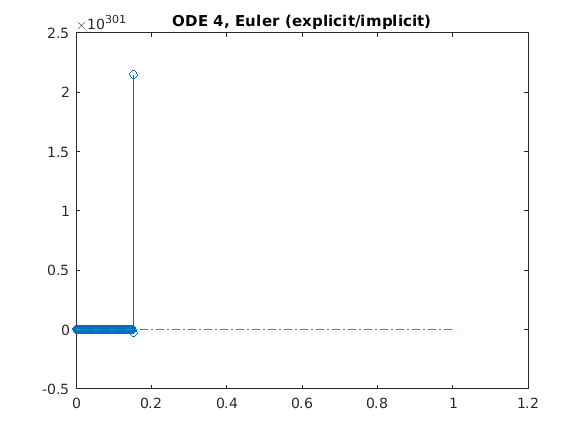

tspan = [0 1];
y0 = [0.5 10];
[~,y_exp] = euler(@(t,y) [y(2), -100000.001*y(2)-100*y(1)], tspan, y0, 0.001); 
[t,y_imp] = euler_imp(@(t,y) [y(2), -100000.001*y(2)-100*y(1)], tspan, y0, 0.001); 
plot(t,y_exp(:,1),'-o',t,y_imp(:,1),'-.')
title('ODE 4, Euler (explicit/implicit)')    

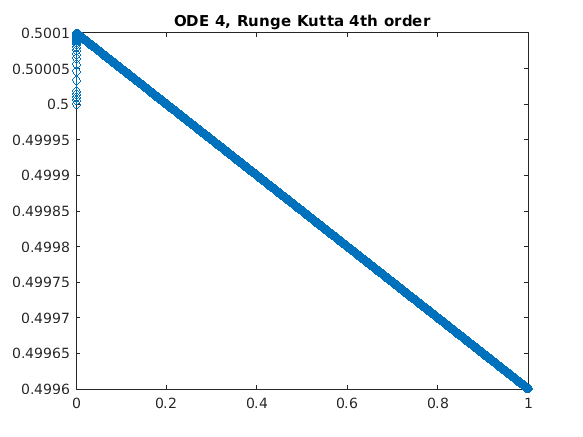

[t,y_45] = ode45(@(t,y) [y(2); -100000.001*y(2)-100*y(1)], tspan, y0);
plot(t,y_45(:,1),'-o')
title('ODE 4, Runge Kutta 4th order')

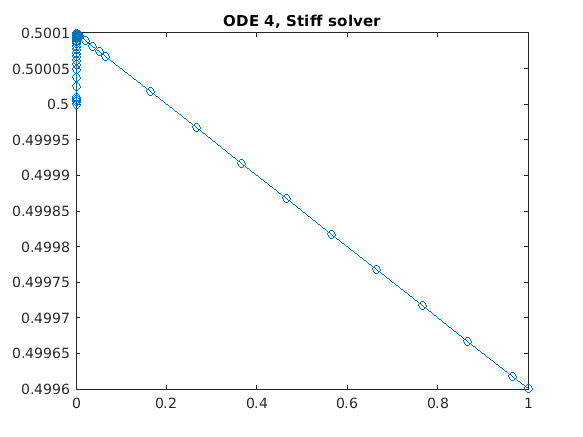

[t,y_15s] = ode15s(@(t,y) [y(2); -100000.001*y(2)-100*y(1)], tspan, y0); 
plot(t,y_15s(:,1),'-o')
title('ODE 4, Stiff solver')